## 1) Correlazione ponderata

Il file regioni.xlsx contiene per ciascuna regione Italiana    

TassoPassaggio=Tasso di passaggio all'Università: immatricolati per 100 diplomati di scuola secondaria di secondo grado dell'anno scolastico precedente;

TassoIscrizione=Tasso di iscrizione all'Università: iscritti all'Università (in qualunque sede) residenti in una certa regione per 100 giovani di 19-25 anni residenti nella stessa regione;

 IscrittiFuoriRegione=Iscritti in sedi universitarie ubicate fuori dalla regione di residenza per 100 iscritti (sono esclusi i cittadini stranieri e gli italiani residenti all'estero);

Residenti=Popolazione residente.

Osservazione: I primi tre indicatori possono ritenersi aspetti diversi della  propensione agli studi universitari in ciascuna regione d'Italia, per cui risulta interessante misurare la relazione esistente tra essi, tramite il calcolo del coeffiente di correlazione lineare. Dato che siamo in presenza di una seria territoriale multipla, appare ragionevole nel calcolo dei diversi indici statistici tenere conto della differente importanza delle regioni.

Mostrare tramite GUI tutti i passaggi necessari per calcolare la correlazione tra le variabili TassoPassaggio  e TassoIscrizione. 

Calcolare la matrice dei coefficienti di correlazione nei 3 diversi modi che seguono:

- Tramite la matrice di varianze e covarianze (v. equazione 6.9 del testo).

- Tramite la matrice degli scostamenti standardizzati. Verificare che le medie e le varianze (oppure le std) delle colonne della matrice Z sono 0 e 1.

- Tramite doppio ciclo for.

Testare l'ipotesi che il vero coefficiente di correlazione sia uguale a 0 nell'universo per ogni coppia di variabili. Calcolare i p-values del test. Mostrare la matrice di correlazione e dei p-values del test di assenza di correlazione in formato table. Commentare i risultati ottenuti

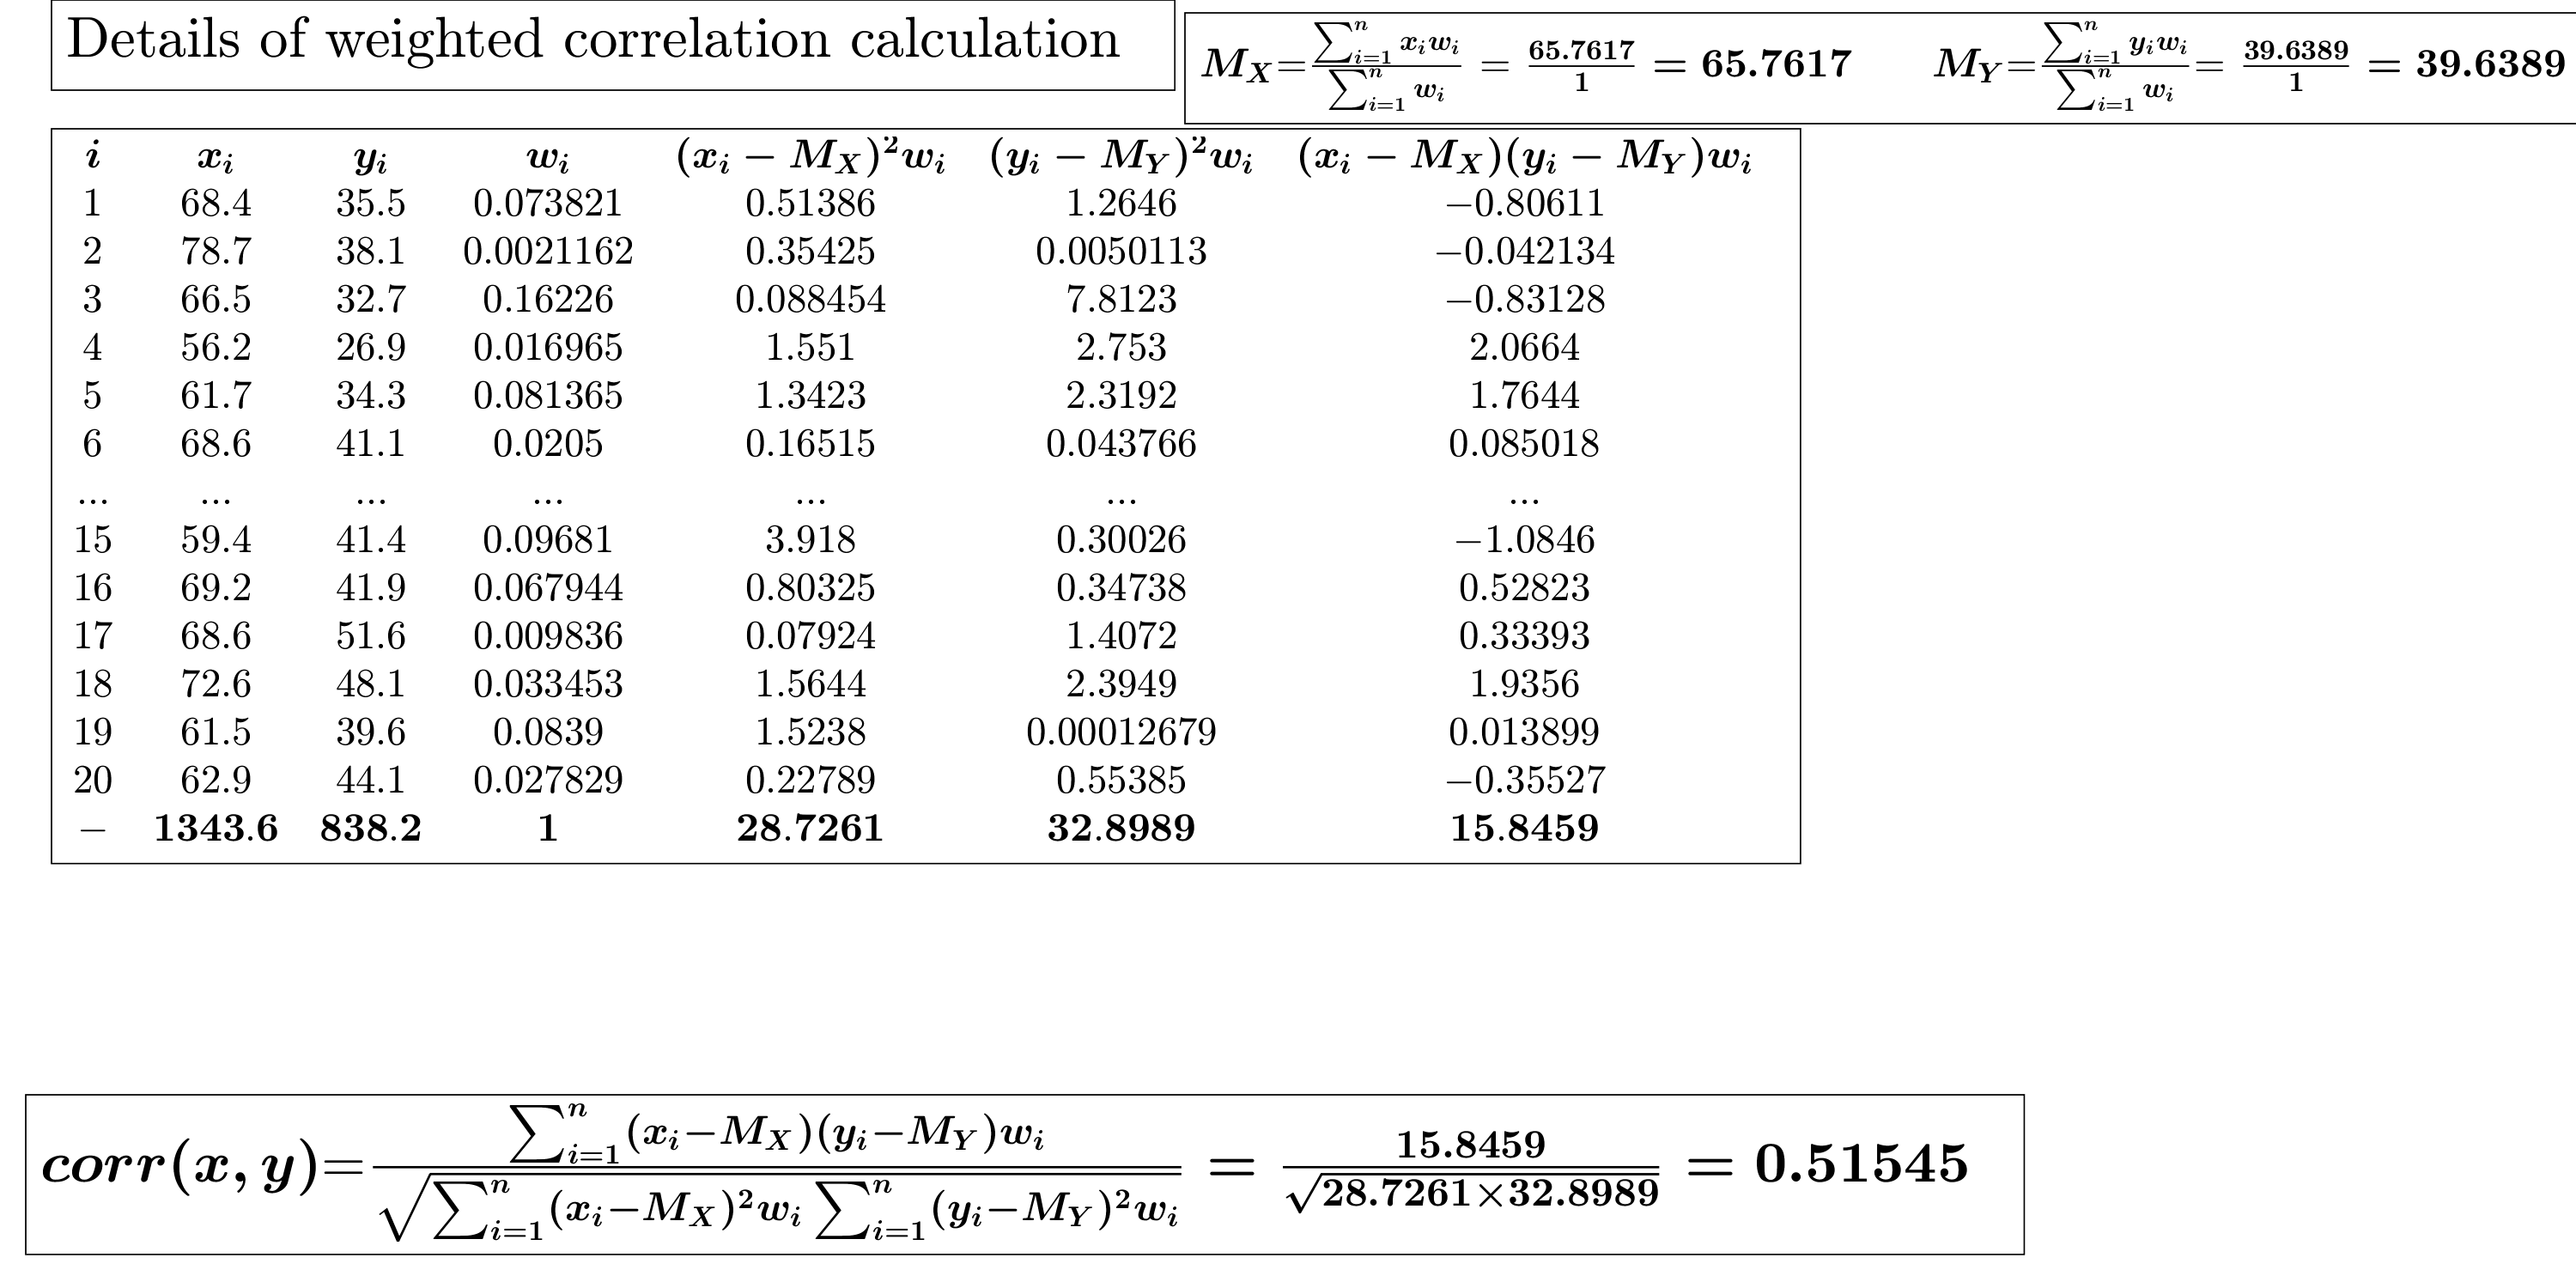

Xtable=readtable("regioni.xlsx",'ReadRowNames',true);
Xd=Xtable{:,1:3};
% Estraggo il vettore dei pesi. Le statistiche devono essere ponderate in
% quanto le regioni hanno una diversa importanza. In questo esempio
% utilizziamo i residenti come variabile peso.
w=Xtable.Residenti;
% Dividere per sum(w) non è necessario in quanto la correlazione è invariante per
% trasformazioni lineari crescenti. Tuttavia lo faccio per convenienza
% computazioanale in modo tale da evitare ogni volta di dividere per la
% somma dei pesi (dato che la somma dei wstar è 1).
wstar=w/sum(w);
% Viene invocata la funzione GUIcorr per mostrare i passaggi relativi al
% calcolo del coefficiente di correlazione ponderato.
out=GUIcorr(Xtable.TassoPassaggio,Xtable.TassoIscrizione,wstar);

% n= numero di osservazioni 
% p =numero di variabili 
[n,p]=size(Xd);

% Calcolo le medie ponderate
% Osservazione: la somma dei pesi è 1 di conseguenza non è necessario
% dividere per la somma dei pesi
mediePonderate=Xd'*wstar;
% Xtilde= Matrice degli scostamenti dalla media
% La media ponderata di ogni colonna della matrice Xtilde è 0
Xtilde=Xd-mediePonderate';

% sqwstar = vettore colonna di lunghezza n che contiene le radici quadrate
% dei pesi associati ad ogni regione
sqwstar=sqrt(wstar);

% S= matrice di varianze e covarianze, ottenuta tramite
% moltiplicazioni matriciali
XtildePesata=(Xd-mediePonderate').*sqwstar;
S=XtildePesata'*XtildePesata;
% stdX= vettore riga di lunghezza p (dove p è il numero di variabili)
% che contiene le standard deviation (pesate)
stdX=sqrt(diag(S)');

% D = matrice diagonale che contiene sulla diagonale principale le standard
% deviation (pesate) delle p variabili originarie
D=diag(stdX);
% Dalla matrice di covarianze ottengo la matrice di correlazione
% Vedi equazione 6.9 del testo data science con MATLAB (formula matriciale per passare dalla matrice di
% covarianze alla matrice di correlazione)
R=D^-1*S*D^-1;
disp("Matrice di correlazione passando attraverso la matrice di covarianze")

Matrice di correlazione passando attraverso la matrice di covarianze


disp(R)

    1.0000    0.5155    0.0782
    0.5155    1.0000    0.2343
    0.0782    0.2343    1.0000




% Z matrice degli scostamenti standardizzati ponderata
% La media ponderata di ogni colonna è 0 e la varianza ponderata di ogni
% colonna della matrice Z è 1.
Z=Xtilde./stdX;

% Verifico che la media ponderata di ogni colonna è 0 e la varianza ponderata di ogni
% colonna della matrice Z è 1.
medieZ=Z'*wstar;
tol=10^-13;
assert(max(abs(medieZ))<tol,"ERRORE: le medie ponderate delle colonne della matrice Z non sono 0")
stdZ=std(Z,wstar);
assert(max(abs(stdZ-1))<tol,"ERRORE: le varianze ponderate delle colonne della matrice Z non sono 1")

Zpesata=Z.*sqwstar;
% L'espressione Zpesata'*Zpesata non è altro che la generalizzazione matriciale
% dell'equazione (7.13) dell'immagine di seguito
Rchk=Zpesata'*Zpesata;
% Un modo alternativo (inefficiente) per calcolare la matrice di
% correlazione era Z'*diag(wstar)*Z
disp("Matrice di correlazione passando attraverso la matrice Z")

Matrice di correlazione passando attraverso la matrice Z


disp(Rchk)

    1.0000    0.5155    0.0782
    0.5155    1.0000    0.2343
    0.0782    0.2343    1.0000



OSSERVAZIONE: questo esercizio è stato estratto dalle pagine 238-239 del libro di Statistica Introduzione all'analisi dei dati statistici (2019) Milioli, Riani e Zani, Pitagore Editore, 

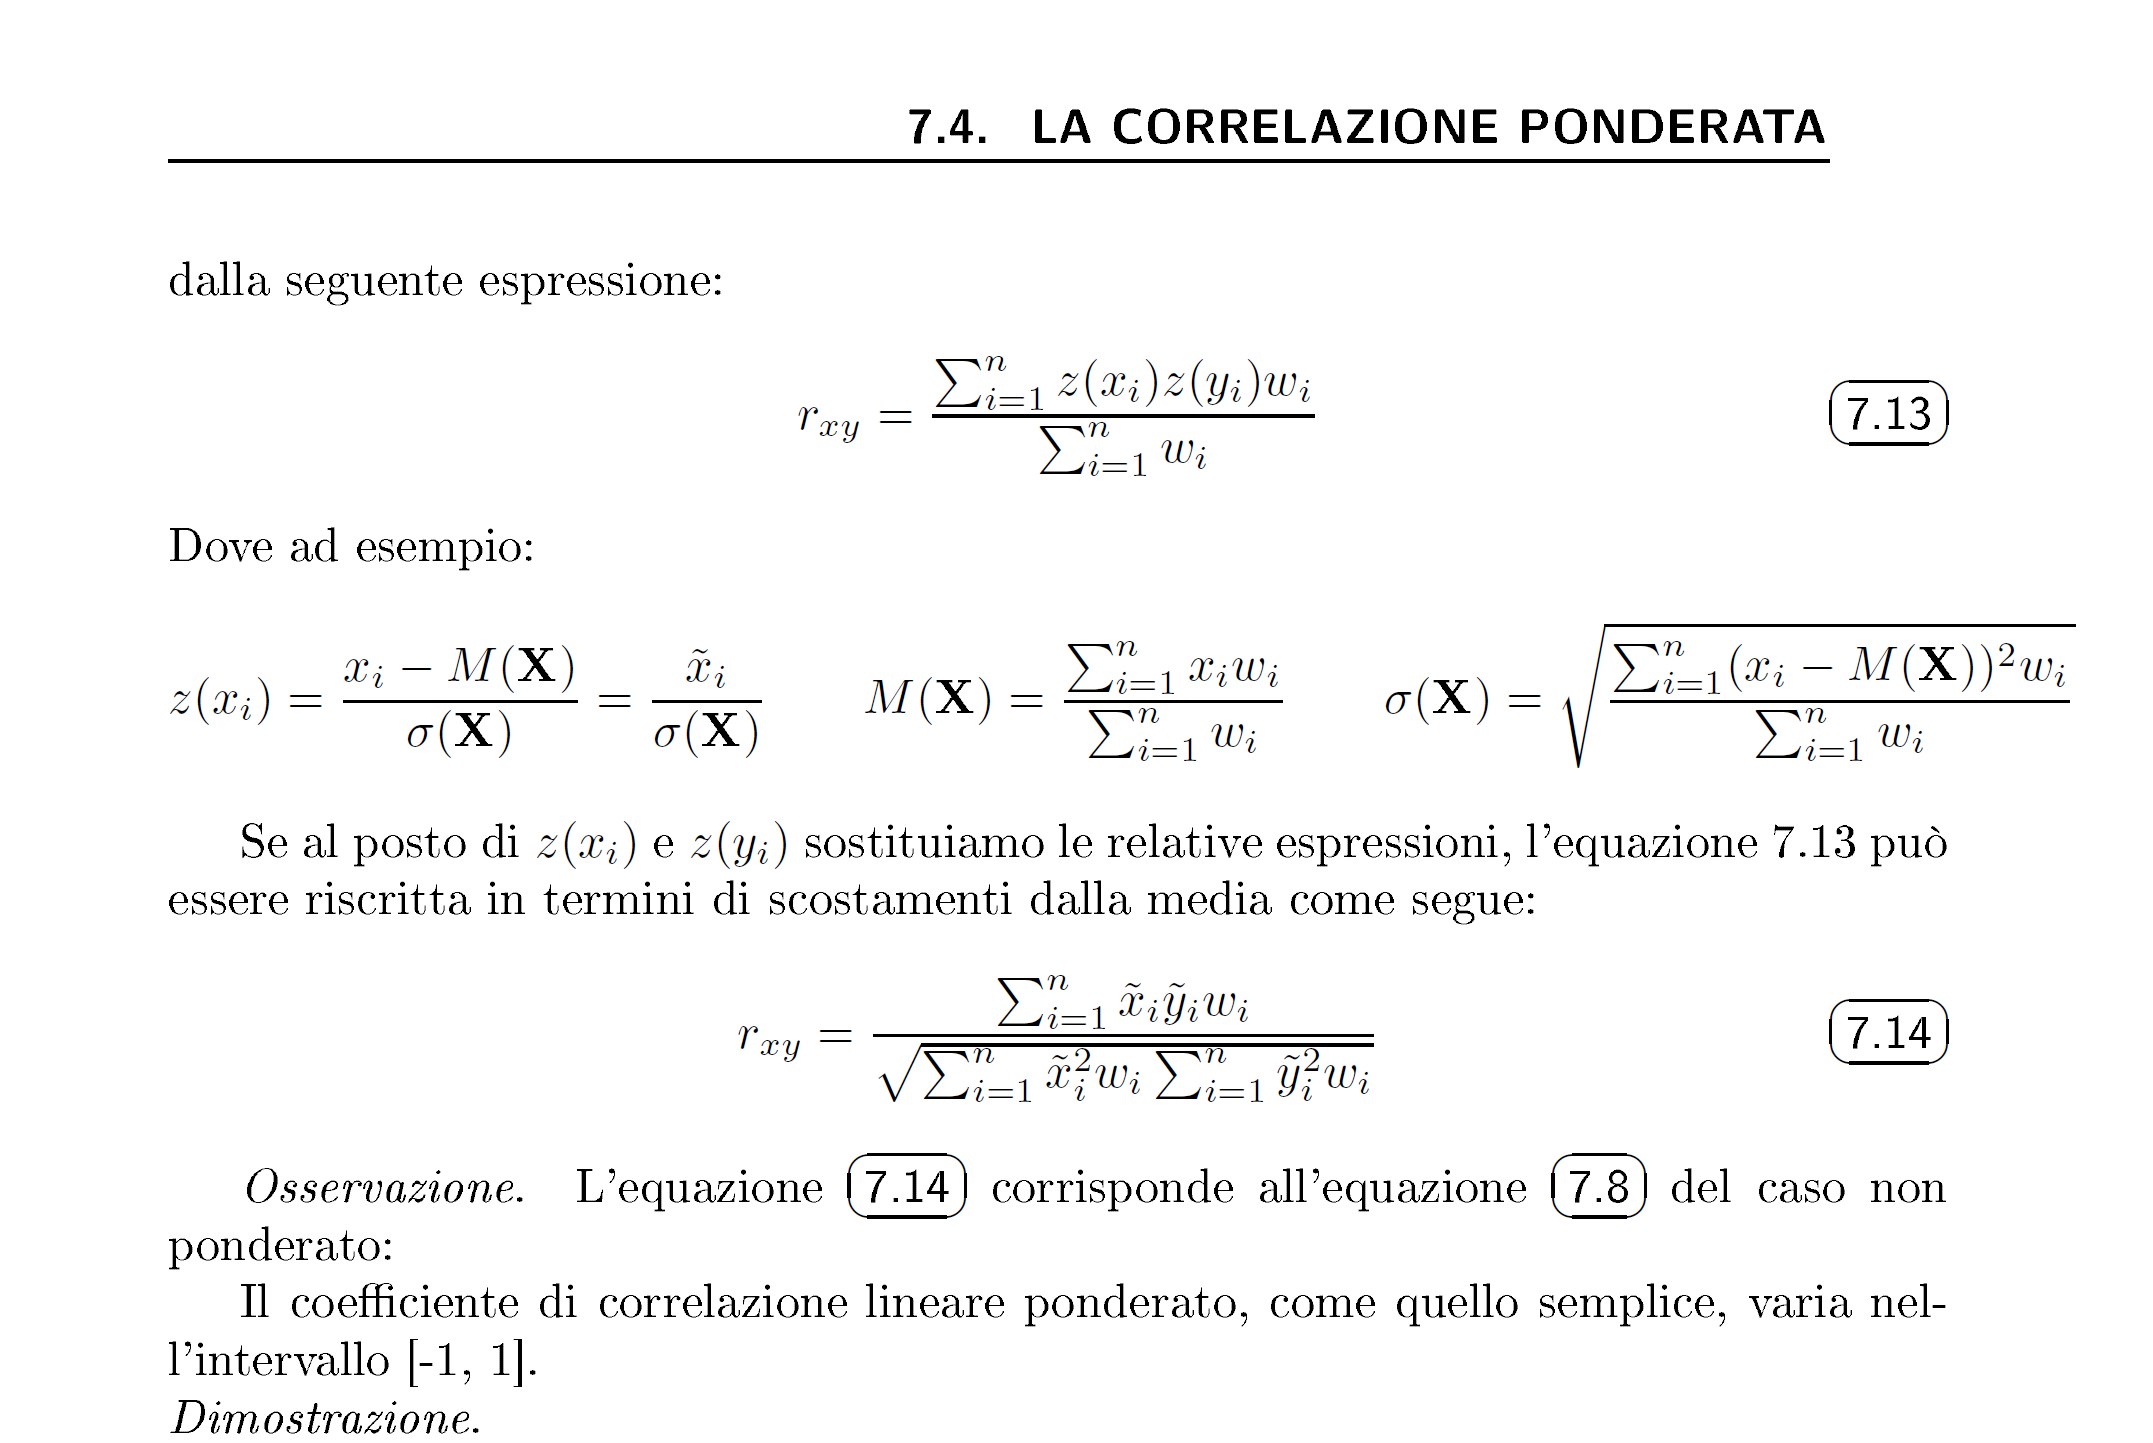

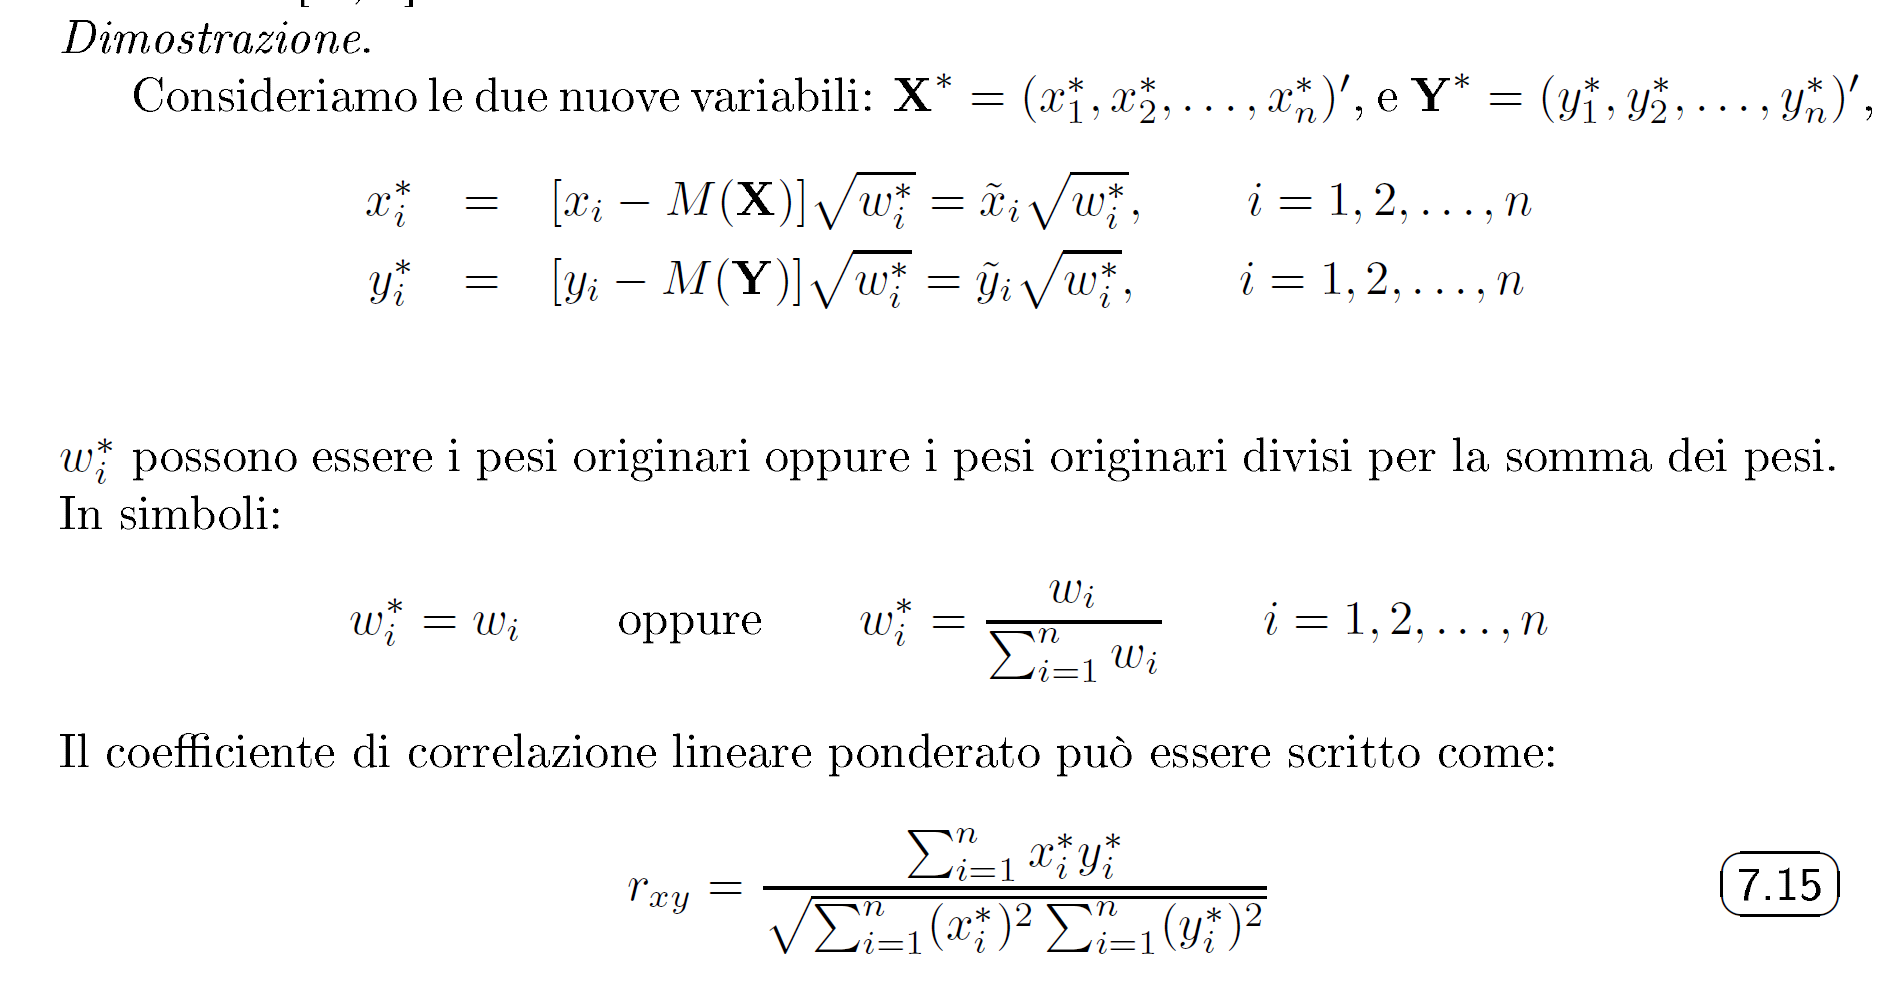

% Di seguito l'implementazione da pivelli tramite cicli for.
% Inizializzo la matrice di correlazione che conterrà i coefficienti di
% correlazione lineare (ponderati)
RdaPivelli=zeros(p,p);
for i=1:p
    % La riga che segue dipende solo dall'indice i e non da j di conseguenza
    % non è efficiente farla ricalcolare ogni volta per ogni j
    xstar=(Xd(:,i)-mediePonderate(i)).*sqwstar;
    for j=1:p
        ystar=(Xd(:,j)-mediePonderate(j)).*sqwstar;
        % Equazione (7.15) dell'immagine sopra applicata all'elemento i,j
        % della matrice di correlazione
        RdaPivelli(i,j)=sum(xstar.*ystar)/sqrt(sum(xstar.^2)*sum(ystar.^2));
        % Ovviamente quando i=j RdaPivelli(i,j)=1
    end
end
disp("Matrice di correlazione tramite implementazione da pivelli")

Matrice di correlazione tramite implementazione da pivelli


disp(RdaPivelli)

    1.0000    0.5155    0.0782
    0.5155    1.0000    0.2343
    0.0782    0.2343    1.0000



% Controllo l'uguaglianza delle diverse implementazioni
tol=1e-12;
AffermazioneDaTestare=max(R-Rchk,[],"all")<tol && max(R-RdaPivelli,[],"all")<tol;
assert(AffermazioneDaTestare,"Le implementazioni sono diverse")

% Calcolo del test di assenza di correlazione per ogni coppia di variabili
Testt=(R./sqrt(1-R.^2))*sqrt(n-2);

% Calcolo dei relativi p-values
Pval=tcdf(abs(Testt),n-2,'upper')*2;
% Aggiungo i valori 1 sulla diagonale principale nella matrice Pval
Pval=Pval +eye(p);

% Dagli array costruisco le table 
nam=Xtable.Properties.VariableNames(1:3);
Pvalt=array2table(Pval,"RowNames",nam,"VariableNames",nam);
Rt=array2table(R,"RowNames",nam,"VariableNames",nam);
disp('Matrice di correlazione')

Matrice di correlazione


disp(Rt)

                            TassoPassaggio    TassoIscrizione    IscrittiFuoriRegione
                            ______________    _______________    ____________________

    TassoPassaggio                    1           0.51545              0.078173      
    TassoIscrizione             0.51545                 1               0.23428      
    IscrittiFuoriRegione       0.078173           0.23428                     1      



disp('Matrice dei p-values dei test di assenza di correlazione')

Matrice dei p-values dei test di assenza di correlazione


disp(Pvalt)

                            TassoPassaggio    TassoIscrizione    IscrittiFuoriRegione
                            ______________    _______________    ____________________

    TassoPassaggio                    1          0.020015              0.74322       
    TassoIscrizione            0.020015                 1              0.32013       
    IscrittiFuoriRegione        0.74322           0.32013                    1       



% La relazione lineare tra TassoPassaggio e IscrittiFuoriRegioni non è
% significativa. Stessa cosa dicasi per la coppia di variabili
% IscrittiFuoriRegione e TassoIscrizione. La relazione tra TassoPassaggio e
% TassoIscrizionen, al contrario, al livello di significativià del 5 per
% cento è significativa. 

## 2) Matrice di correlazione

Caricare in memoria il file head.mat di FSDA toolbox. Per la descrizione di questo dataset si veda l'Esercizio 8.5 del testo oppure la pagina [Flexible Statistics and Data Analysis Toolbox Functions - - By Category (unipr.it)](http://rosa.unipr.it/FSDA/datasets_mv.html). Calcolare e commentare la matrice di correlazione delle 6 variabili. 

Verificare l'ipotesi di assenza di correlazione per ogni coppia di variabili. Calcolare e commentare i relativi p-values. Mostare la matrici di correlazione e quella dei relativi p-values in formato table. Utilizzare come nomi delle variabili nelle due tables la parola che segue l'ultimo underscore. Ad esempio, se nella table originaria head una variabile si chiama length_tragion_nasion si deve estrarre la parola nasion. Mostrare l'output utilizzando solo due cifre decimali.

clear % cancella tutte le variabili presenti in memoria
%% Caricamento della table head in memoria
load head
% X = dataset in formato double (solo numeri)
X=head{:,:};
% Costruzione della matrice di correlazione e dei relativi p-values
[R,Pval]=corr(X);
% nomivar è deifnito come vettore colonna
nomivar=head.Properties.VariableNames';
% Viene utilizzata la funzione split per separare le parole contenute nel
% cell array nomivar
nomiSeparati=split(nomivar,'_');
% Le parole che seguono l'ultimo underscore sono riportate nella colonna 3
% di nominuovi
nominuovi=nomiSeparati(:,3);

PvalT=array2table(Pval,"RowNames",nominuovi,"VariableNames",nominuovi);
RT=array2table(R,"RowNames",nominuovi,"VariableNames",nominuovi);

% Imposto il formato con solo due cifre decimali (vedi sezione 1.8.3 del
% testo)

                  breadth    mandibulae    height    nasi    nasion    gnathion
                  _______    __________    ______    ____    ______    ________

    breadth        1.00         0.47        0.17     0.13     0.40       0.41  
    mandibulae     0.47         1.00        0.09     0.09     0.35       0.39  
    height         0.17         0.09        1.00     0.41     0.26       0.24  
    nasi           0.13         0.09        0.41     1.00     0.18       0.21  
    nasion         0.40         0.35        0.26     0.18     1.00       0.66  
    gnathion       0.41         0.39        0.24     0.21     0.66       1.00  



format bank

                  breadth    mandibulae    height    nasi    nasion    gnathion
                  _______    __________    ______    ____    ______    ________

    breadth        1.00         0.00        0.01     0.06     0.00       0.00  
    mandibulae     0.00         1.00        0.19     0.19     0.00       0.00  
    height         0.01         0.19        1.00     0.00     0.00       0.00  
    nasi           0.06         0.19        0.00     1.00     0.01       0.00  
    nasion         0.00         0.00        0.00     0.01     1.00       0.00  
    gnathion       0.00         0.00        0.00     0.00     0.00       1.00  



disp(RT)
disp(PvalT)

% Tutti i coefficienti di correlazione lineare sono positivi.
% Quasi tutte le correlazioni risultano significative.  Questo significa
% che ad una faccia con valori (ad esempio) elevati della lunghezza della
% mandibola (mandibulae), corrispondono elevati di (ad esempio) lunghezza del naso. Alle
% facce più larghe (breadth) corrisponono altezze facciali (height) più
% elevate...
